# **Modeling of Passive Solar House in Boston, MA**

## **I**ntroduction

#### What is a passive solar home?

Passive solar houses are incredible. By definition passive solar houses they use energy from the sun and their surroundings to maintain a livable internal temperature. Everyone should be interested in building one as passive homes are much cheaper to heat and cool since they are designed in such a way to naturally maintain reasonable temperatures. 

Passive solar homes are built on the principle of storing energy from the sun. At a base level they require: 

- A large thermal mass (like stone floors) to store energy from the sun

- Large south facing windows to collect sun, specifically in the winter months

- Some form of insulation to reduce heat loss

- Other controls/design choices to block sun in certain situations (eaves, trees, etc)

#### What's our strategy?

Designing a passive solar house for the Boston area where it gets very cold in the winter will require careful design of the house. In attempt to maintain a stable internal temperature, our first model/design will incorporate the following features:

- Extremely large south facing window

- Eaves that protect the windows/thermal mass during the summer

- A tile floor that act's as a large thermal mass

- No windows in any other walls

- A very tiny floorplan (~200sqft)

- Insulation in the ceiling, walls, and floor

## The Model

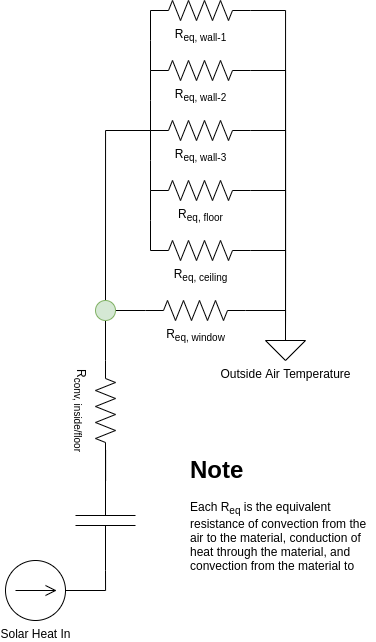

#### Governing  ODE's

The behavior of the various parts of the house can be modeled using a set of Ordinary Differential Equations. (ADD MORE EXPANATION ETC HERE)

This simple house makes use of just 2 ODEs. The first ODE describes the rate of change of the temperature of the floor ($T_{floor}$) in realtion to time. This value depends on the amount of energy coming into the floor via solar radiation ($Q_{in}$). The floor also loses energy to its surroundings through the walls. This is accounted for in the second part of the equation. This part takes into account the resistance from the floor to the outside air, as well as the temperature differential. 

The inside air temperature can be modeled as a linear function of the floor temperature. This is described by the second function.

*ODE describing rate of change of the Temp of the floor*


$$\frac{dT_{floor}}{dt} =\frac{Q_{in}}{C_{floor}} - \frac{ T_{floor}-T_{out}}  {C_{floor}\cdot R_{total}} $$


*Realtionship between the Temp of the air inside the house and the floor*


$$T_{inside\ air} = \frac{R_{parallel}}{R_{total}}\cdot T_{floor}
$$
 

#### Assumptions

Key assumptions allow the simplification of this complex system to the above equations. These include:

- Air doesn't enter or leave the house

- Insulation is purely a resistance, it doens't store any heat

- The only heat storage is in the large thermal mass

- Outside air is a constant temperature

- Radiation only hits the window and the heat storage unit

- Heat transfer and resistance is the same for all walls, floors, and ceilings

- Heat storage unit is at spatially uniform temperature

### Parameters

#### Time

% Number of days to run the model
days = 14;

% Timespan for the model
step_size = 180;
time_span = [0:step_size:60*60*24*days];

#### Dimensions

% Internal dimensions of inside air
house.x = 5.0; % meters
house.y = 3.0; % meters
house.z = 5.0; % meters
house.sq_ft = house.x * house.z * 10.7639; % ft^2
house.eave = 0.9; % m % Length of the eave of the house

% Window
window.h = 0.7;
window.y = 2.0; % m;
window.z = house.z-.5; % m % Window has a half meter wall on either side
window.area = window.y * window.z; % m^2
window.y_offset = 0.2; % m % Height off the ground

% Floor
floor.x = house.x;
floor.z = house.z; 
% PARAM %
floor.y = 0.3; % meters
floor.density = 3000.0; % kg/m^3
floor.spec_heat = 800.0; % J/kg*K
floor.mass = floor.x * floor.y * floor.z * floor.density; % kg
floor.T_0 = 0; % C
floor.sa = 2*floor.x*floor.y + 2*floor.x*floor.z + 2*floor.y*floor.z; % m^2 % Surface area

% Walls
house.ceiling_floor_area = house.z * house.x; % m^2
house.side_wall_area = house.x * house.y; % m^2
house.anti_window_wall_area = house.z * house.y; % m^2 % Wall opposite window
house.window_wall_area = house.anti_window_wall_area - (window.area) + window.y*(house.z-window.z); % m^2

% PARAM %
insulation.thickness = 0.06; % meters
insulation.k = 0.04; % W/m*K % Thermal conductivity constant
insulation.total_area = 2*house.ceiling_floor_area + 2*house.side_wall_area + house.anti_window_wall_area + house.window_wall_area; % m^2

#### Air Temperature

outside_air.T = -3; % degrees celcius
outside_air.h = 30.0; % W/m^2*K


$$T_{outside\ air} = -3 + 6 \cdot \sin(\frac{2t\pi}{24 \cdot60\cdot60}) + \frac{3\pi}{4}$$


outside_air.sin = @(t) (-3 + 6*sin((2*pi*t)/(24*60*60) + (3*pi)/4)); % Degrees celcius

inside_air.T_0 = 0; % degrees celcius
inside_air.h = 15.0; % W/m^2*K

#### Heat

% W/m^2
solar_flux = -361 .* cos((pi.*time_span)./(12*3600)) + 224 .* cos((pi.*time_span)./(6*3600)) + 210;
floor.heat_in = solar_flux .* window.area; % W

### Resistances/Capacities

floor.heat_cap = floor.spec_heat * floor.mass; % J/K

% Resistance through all the insulation
R_air_wall = (inside_air.h * insulation.total_area)^-1; % Convection, K/W
R_wall = insulation.thickness / (insulation.k * insulation.total_area); % Conduction, K/W
R_wall_outside = (outside_air.h * insulation.total_area)^-1; % Convection, K/W
R_wall_total = R_air_wall + R_wall + R_wall_outside; % K/W

% Resistance through the window
R_air_window = (inside_air.h * window.area)^-1; % Convection, K/W
R_window = (window.h * window.area)^-1; % Conduction, K/W
R_window_outside = (outside_air.h * window.area)^-1; % Convection, K/W
R_window_total = R_air_window + R_window + R_window_outside; % K/W

R_loss = (sum([R_wall_total R_window_total].^-1))^-1;

R_floor_air = (inside_air.h*floor.sa)^-1; % Resistance from floor to inside air

R_total = R_floor_air + R_loss; % Total resistance from floor to outside air

### ODEs and other Relationships

*ODE describing rate of change of the Temp of the floor*


$$\frac{dT_{floor}}{dt} =\frac{Q_{in}}{C_{floor}} - \frac{ T_{floor}-T_{out}}  {C_{floor}\cdot R_{total}} $$


*Relationship describing rate of change of the Temp of the air inside the house*


$$T_{inside\ air} = \frac{R_{parallel}}{R_{total}}\cdot T_{floor}
$$
 

### First pass model with constant outside temperature

Qin = @(t) (-361 * cos((pi*t)/(12*3600)) + 224 * cos((pi*t)/(6*3600)) + 210) * window.area;

f = @(t,T) [Qin(t)/floor.heat_cap - (T(1)-outside_air.T)/(R_total*floor.heat_cap);];

[t,T_sol] = ode45(f,time_span,[0]);
T_sol(:,2) = T_sol(:, 1) * (R_loss/R_total); % Use voltage divider analogy to calculate internal air temp

Graphed,

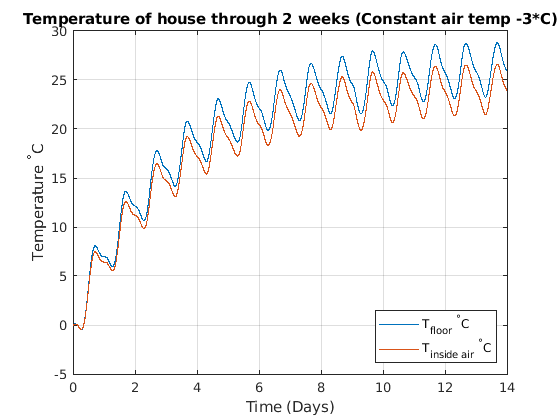

plot_ode(t, T_sol)
title("Temperature of house through 2 weeks (Constant air temp -3*C)")

### Second pass model with outside temperature as a sin function

% TODO ADD Comments
f = @(t,T) [Qin(t)/floor.heat_cap - (T(1)-outside_air.sin(t))/(R_total*floor.heat_cap);];
[t_sin,T_sol_sin] = ode45(f,time_span,[0]);

T_sol_sin(:,2) = T_sol_sin(:, 1) * (R_loss/R_total); % Use voltage divider analogy to calculate internal air temp

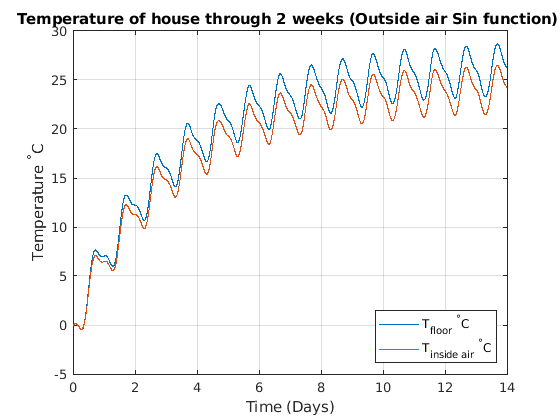

plot_ode(t_sin, T_sol_sin)
title("Temperature of house through 2 weeks (Outside air Sin function) ")

### Single day

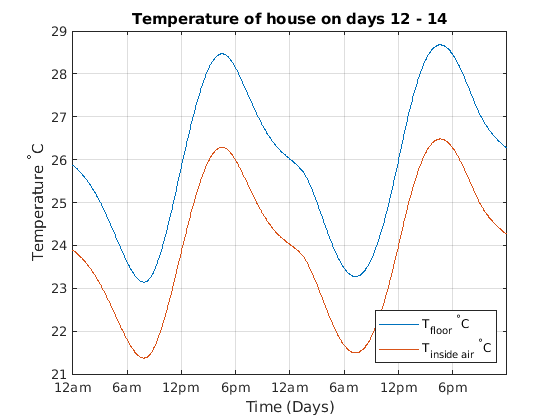

day_start = 12;
day_end = 14;
day_ticks = ["12am","6am","12pm","6pm",];
seconds_in_day = 24*3600/180;
day_start_index = 1+day_start*seconds_in_day;
day_end_index = day_end*seconds_in_day;

figure
plot(t_sin(day_start_index:day_end_index,:)/(60*60*24), T_sol_sin(day_start_index:day_end_index,1), "DisplayName", "T_{floor} ^{\circ}C");
hold on;
plot(t_sin(day_start_index:day_end_index,:)/(60*60*24), T_sol_sin(day_start_index:day_end_index,2), "DisplayName", "T_{inside air} ^{\circ}C");
hold off;
add_axis
xticks(day_start:1/4:day_end)
xticklabels(repmat(day_ticks, 1, day_end-day_start));
%xticklabels(["Midnight","6am","Noon","6pm","Midnight"])
title("Temperature of house on days " + day_start + " - " + day_end)

### Analyzing heat absorbed through the window for one day and temperature change

We were concerned with how hot our floor/house was getting (~60*C). To take a look at possible explanations for this behavior we wanted to look at how much energy was coming into the house. 


$$Q_{in} = (-361 \cdot \cos(\frac {t\pi}{12 \cdot 3600}) + 224 \cdot \cos(\frac {t\pi}{6 \cdot 3600}) + 210) \cdot A_{window.area}$$


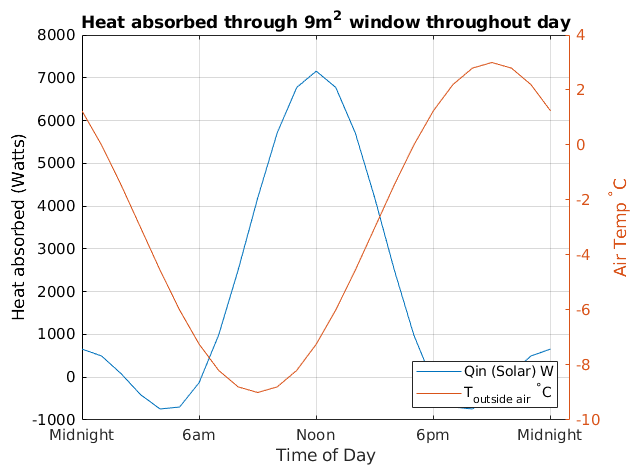

one_day = [0 : 60*60 : 24*3600];
solar_day = Qin(one_day);
out_air = outside_air.sin(one_day);

figure
plot(one_day/3600, solar_day, "DisplayName", "Qin (Solar) W");
yyaxis right
plot(one_day/3600, out_air , "DisplayName", "T_{outside air} ^{\circ}C");
xticks([0,6,12,18,24]);
xticklabels([["Midnight","6am","Noon","6pm","Midnight"]])
grid on; legend("Location", "Southeast");
xlabel("Time of Day")
ylabel("Air Temp ^{\circ}C")
yyaxis left
ylabel("Heat absorbed (Watts)")
title("Heat absorbed through " + window.area + "m^2 window throughout day")

This plot shows the amount of energy coming into the house at various points of the day for our given window size. It also shows the outside temperature of the house throughout the day. Together, these curves explain the shape of the floor temperature curve seen in one day.

At it's peak, there is ~10,000 watts coming into the house. This value seemed really high at first! However, according to some sources, this is likely realistic. Tennessee Solar info indicates that at the surface of the earth in good conditions solar flux could be around ~1000 w/m^2. Our window is 13m^2 which indicates that our max solar flux is < 1000W/m^2 and is likely within an acceptable range.

### Sweeping through parameters

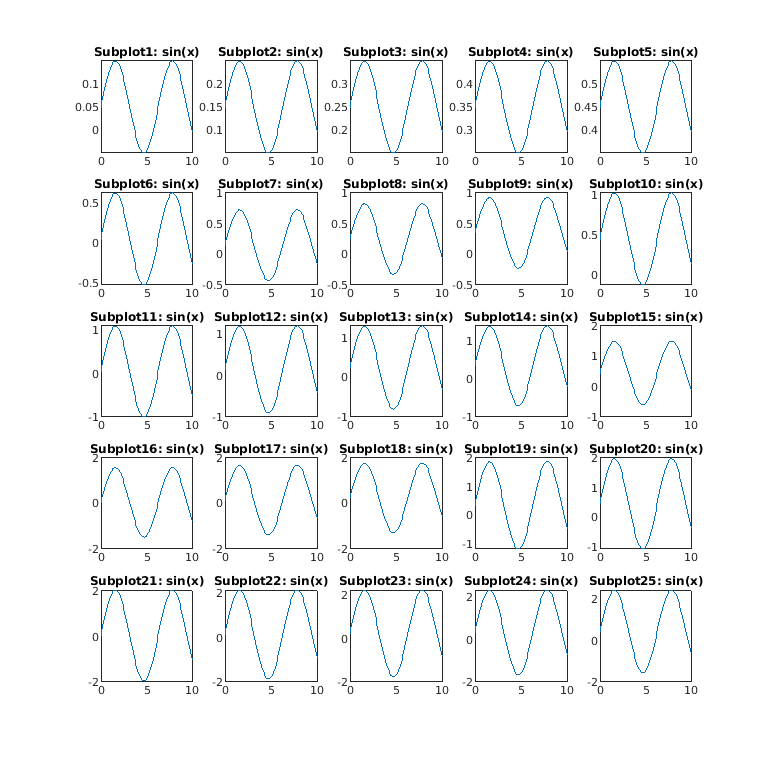

values = 5;
min_insul = 0.01;
max_insul = 0.20;
min_floor_thick = 0.05;
max_floor_thick = 0.45;
min_window = -1;
max_windpw = 0;
insul_range = linspace(min_insul, max_insul, values);
floor_range = linspace(min_floor_thick, max_floor_thick, values);

plot_num = 1;
x = linspace(0,10);
figure1=figure('Position', [100, 100, 2000, 2000]);
for i = insul_range
    for k = floor_range
        subplot(values,values,plot_num)
        y1 = 10*i*sin(x)+k;
        plot(x,y1)
        title("Subplot"+ plot_num + ": sin(x)")
        plot_num = plot_num + 1;
    end
end

TODOOOO

- JACK Single day plots of house

- JACK Comment code!

- JACK change diagram

- JACK Writeup extensions

Extras

- Cad

- Sweeps/looking at max temps

Sections

- Background

- Model

- Optim

- Discussion

- Bib

function a = plot_ode(x,y)
    figure
    plot(x/(60*60*24), y(:,1), "DisplayName", "T_{floor} ^{\circ}C");
    hold on;
    plot(x/(60*60*24), y(:,2), "DisplayName", "T_{inside air} ^{\circ}C");
    hold off;
    add_axis
end
function a = add_axis()
    grid on; legend("Location", "Southeast");
    xlabel("Time (Days)"); ylabel("Temperature ^{\circ}C");
end